# Acoustic Triangulation System Simulation using TDoA Technique

## Authors: Bonga Njamela, Charles Portman, Morris Nkomo

## Date: 12 Sept 2023

## We simulate TDoA measurements from a single sound source and use them to localize and track the source in the absence of noise and any other signals that can lead to missed detections. Adapted from mathworks simulation.

## 1. Define 2-D Scenario



% Define a 2-D scenario using the helper function which returns a
% trackingScenarioRecording object representing a single sound source
% moving at a constant velocity. The sound source is observed by 4
% stationary, spatially-separated microphones. The helper function also
% returns a matrix of two columns representing the pairs formed by the
% receivers. Each row represents the PlatformID of the platforms that form
% the TDoA measurement.

% Reproducible results
rng(2021);

% Setup scenario with 4 receivers
numReceivers = 4;
[scenario, rxPairs] = helperCreateSingleTargetTDOAScenario(numReceivers);

Unrecognized function or variable 'helperCreateSingleTargetTDOAScenario'.

## 2. Simulate TDoA Measurements from Sound Source

% Use helperSimulateTDOA function to simulate TDoA measurements from the
% objects. The helper function allows you to specify the measurement
% accuracy in the TDoA. The timing inaccuracy in the clocks as well as TDoA estimations is assumed to
% be 100 ns. The emission speed and units of the reported time can be
% specified using the helperGetGlobalParameters funciton. The
% helperSimulateTDoA function returns the TDoA detections as a cell array
% of objectDetection objects.

%helperGetGlobalParameters(); %set speed of sound c
measNoise = 1000; %measurement noise variance nanosecond^2
tdoaDets = helperSimulateTDOA(scenario, rxPairs, measNoise);

% Each TDoA detection is represented using the objectDetection according to the following format:



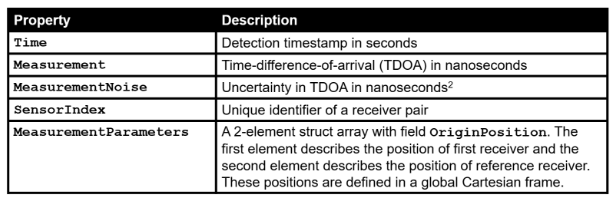

## 3. Genertate TDoA Detections From Sound Source

% Use the helperTDOA2Pos function to estimate the position and position
% covariance of the acoustic source at every step using the spherical intersection
% algorithm. Further filter the position estimate of the object using a global nearest 
% neighbor (GNN) tracker configured using the trackerGNN System object™ with a 
% constant-velocity linear Kalman filter. To account for the high speed of the object, this 
% constant velocity Kalman filter is configured using the helper function, helperInitHighSpeedKF.

% Define accuracy in measurements
measNoise = (100)^2; % nanoseconds^2

% Display object
display = HelperTDOATrackingExampleDisplay(XLimits=[-1e4 1e4],...
                                           YLimits=[-1e4 1e4],...
                                           LogAccuracy=true,...
                                           Title="Single Object Tracking");

% Create a GNN tracker
tracker = trackerGNN(FilterInitializationFcn=@helperInitHighSpeedKF,...
                     AssignmentThreshold=100);

while advance(scenario)
    % Elapsed time
    time = scenario.SimulationTime;

    % Simulate TDOA detections without false alarms and missed detections
    tdoaDets = helperSimulateTDOA(scenario, rxPairs, measNoise);

    % Get estimated position and position covariance as objectDetection
    % objects
    posDet = helperTDOA2Pos(tdoaDets,true);

    % Update the tracker with position detections
    tracks = tracker(posDet, time);

    % Display results
    display(scenario, rxPairs, tdoaDets, {posDet}, tracks);
end
